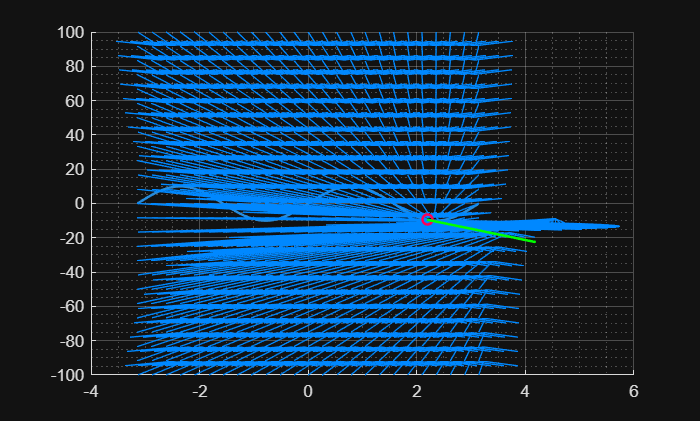

clear;
clc;

syms x;

f = 10*sin(2*x);
fm = matlabFunction(f, "Vars",x);
fx = diff(f,1);
fxm = matlabFunction(fx, "Vars",x);

x1 = linspace(-pi, pi, 100);
y1 = fm(x1);

k = 1;

[a, b] = meshgrid(linspace(-pi, pi, 25), linspace(-100, 100, 25));

figure;
hold on;
grid on; grid minor;
plot(x1, y1, lineWidth=1.5);

i = 1;
for t=x1
    psir = atan(fxm(t));
    theta = atan2(fm(t) - b, t - a);
    r = sqrt((fm(t) - b).^2 + (t - a).^2);


    psid = wrapToPi(psir - (psir - theta).*(2/pi).*atan(k*r.^2 ./(1+r)));
    
    u = cos(psid);
    v = sin(psid);

    if i ~= 1
        delete(h1);
        delete(h2);
        delete(h3);
    end
    h1 = quiver(a, b, u, v, 1, color="#0088ff");
    h2 = plot(t, fm(t), "o", lineWidth=1.5, color="#ff0055");
    h3 = plot([t, t + 2], [fm(t), fm(t) + 2*fxm(t)], lineWidth=1.5, color="g");

    pause(0.1);

    i = i + 1;
end






hold off;
